## Задание 1. Непрерывное и дискретное преобразование Фурье

### ***Истинный Фурье-Образ и Численное интегрирование***

Рассмотрим прямоугольную функцию $\prod :\mathbb{R}\to \mathbb{R}:$


$$\prod \left(t\right)=\left\lbrace \begin{array}{ll}
1, & |t|\le \frac{1}{2}\\
0, & |t|>\frac{1}{2}
\end{array}\right.$$


Создаём вектора частот и времени для работы с преобразованием Фурье...

T = 2000; counter = 1;
dt = 0.1;
t=-T/2:dt:T/2;
V = 1/dt; % Ширина диапазона частот
dv = 1/T; % Шаг частоты 
v = -V/2 : dv : V/2; % Набор частот для FFT


**График прямоугольной функции**

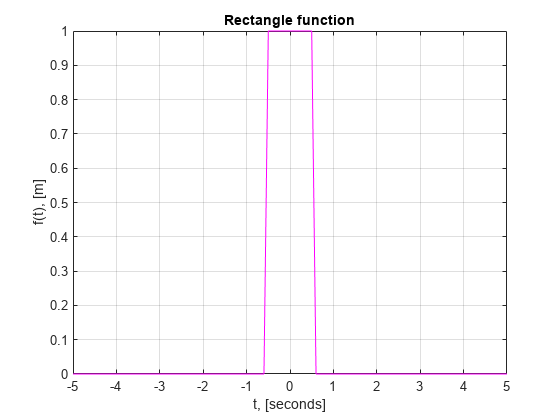

% figure( randi([1 3000],1,1) );
figure;
plot(t, rectangle(t), 'magenta');
grid on
xlabel('t, [seconds]');
xlim([-5, 5])
title("Rectangle function")
ylabel('f(t), [m]');
hold off;

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

**График образа Фурье прямоугольной функции**

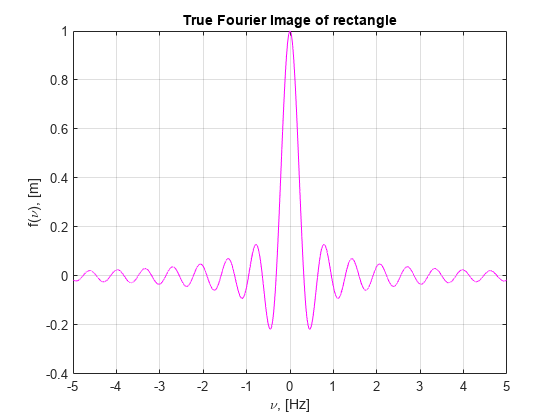

figure;
plot(v, sinc(pi*v), 'magenta');
grid on
xlabel('\nu, [Hz]');
title("True Fourier Image of rectangle")
ylabel('f(\nu), [m]');
hold off;

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

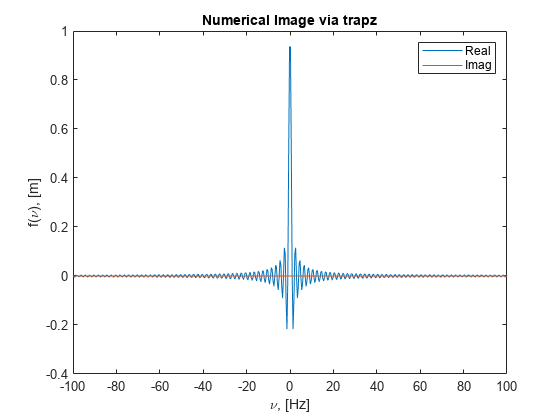

T = 1; % period of the rectangle function - f0
t = linspace(-T, T, 500); % time vector

rect_func = ones(size(t));
rect_func(t < -0.5 | t > 0.5) = 0;

% Define the frequency vector
f = linspace(-100, 100, 500); % frequency vector

% Initialize the DFT vector
DFT = zeros(size(f));

% Compute the DFT for each frequency
for i = 1:length(f)
    DFT(i) = trapz(t, rect_func .* exp(-1j * 2 * pi * f(i) * t));
end

figure;
plot(f, real(DFT));
hold on
plot(f, imag(DFT));
xlabel('\nu, [Hz]');
ylabel('f(\nu), [m]');
xlim([-100, 100])
title('Numerical Image via trapz');
legend('Real', 'Imag')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

Давайте возвращаться назад...

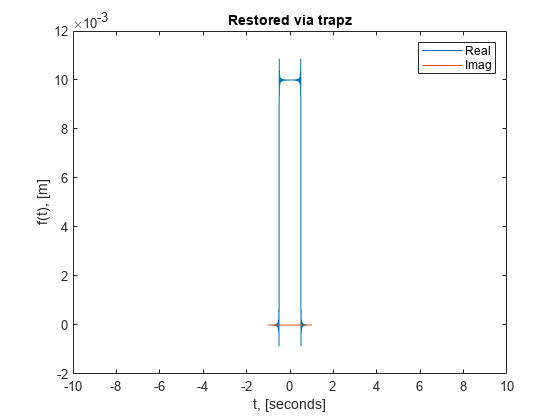

% Initialize the DFT vector
IDFT = zeros(size(f));

% Compute the DFT for each frequency
for i = 1:length(f)
    IDFT(i) = trapz(t, DFT .* exp(1j * 2 * pi * f(i) * t));
end

figure;
plot(t, real(IDFT));
hold on
plot(t, imag(IDFT));
title("Restored via trapz")
xlim([-10, 10])
xlabel('t, [seconds]');
ylabel('f(t), [m]');
legend('Real','Imag')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

Возьмём сразу большой шаг, потому что в идеале мы должны интегрировать на всей числовой оси, а мы здесь берём конечный промежуток, поэтому идеального восстановления такими методами нам точно не добиться. Но уже на таком шаге можно заметить, что мы неплохо приближаем прямоугольник, но пока что нам мешает то, что у нас остается периодичность в обратную сторону.

*Теперь возьмём большой промежуток при такой же дискретизации...*

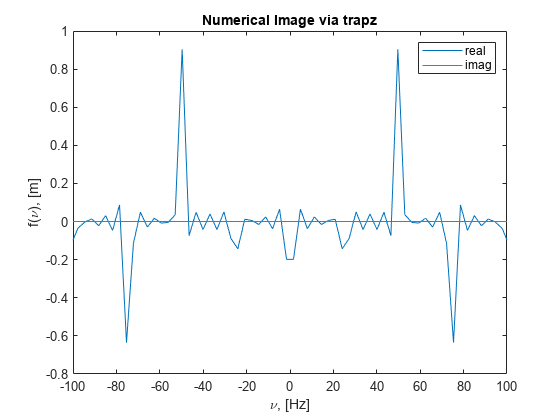

T = 10; % period of the rectangle function - f0
count = 500;
t = linspace(-T, T, count);

rect_func = ones(size(t));
rect_func(t < -0.5 | t > 0.5) = 0;

% Define the frequency vector
f = linspace(-800, 800, 500); % frequency vector

% Initialize the DFT vector
DFT = zeros(size(f));

% Compute the DFT for each frequency
for i = 1:length(f)
    DFT(i) = trapz(t, rect_func .* exp(-1j * 2 * pi * f(i) * t));
end

figure;
plot(f, real(DFT));
hold on;
plot(f, imag(DFT));
xlabel('\nu, [Hz]');
ylabel('f(\nu), [m]');
xlim([-100, 100])
title('Numerical Image via trapz');
legend('real', 'imag')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

Давайте возвращаться назад...

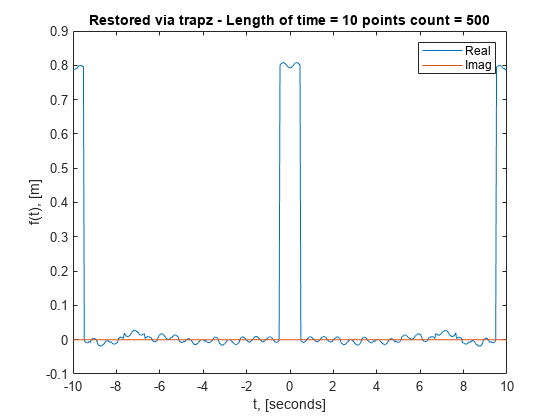

% Initialize the DFT vector
IDFT = zeros(size(f));

% Compute the DFT for each frequency
for i = 1:length(f)
    IDFT(i) = trapz(t, DFT .* exp(1j * 2 * pi * f(i) * t));
end

figure;
plot(t, real(IDFT));
hold on
plot(t, imag(IDFT));
title("Restored via trapz - Length of time = " + T + " points count = " + count)
xlabel('t, [seconds]');
ylabel('f(t), [m]');
legend('Real','Imag')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

*А теперь у этого большого промежутка повысим дискретизацию...*

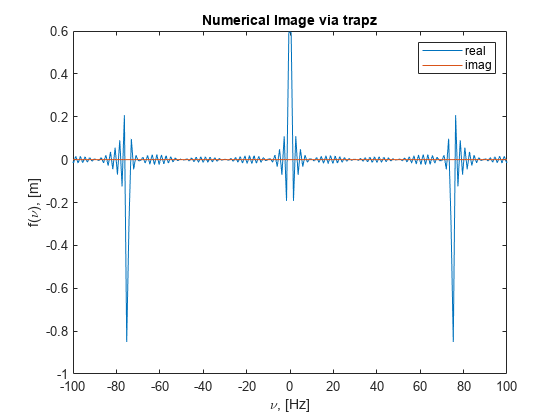

T = 10; % period of the rectangle function - f0
count = 1500;
t = linspace(-T, T, count);

rect_func = ones(size(t));
rect_func(t < -0.5 | t > 0.5) = 0;

% Define the frequency vector
f = linspace(-800, 800, 1500); % frequency vector

% Initialize the DFT vector
DFT = zeros(size(f));

% Compute the DFT for each frequency
for i = 1:length(f)
    DFT(i) = trapz(t, rect_func .* exp(-1j * 2 * pi * f(i) * t));
end

figure;
plot(f, real(DFT));
hold on;
plot(f, imag(DFT));
xlabel('\nu, [Hz]');
ylabel('f(\nu), [m]');
xlim([-100, 100])
title('Numerical Image via trapz');
legend('real', 'imag')


path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

Давайте возвращаться назад...

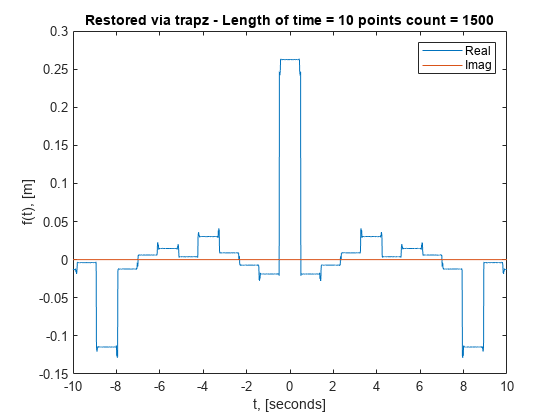

% Initialize the DFT vector
IDFT = zeros(size(f));

% Compute the DFT for each frequency
for i = 1:length(f)
    IDFT(i) = trapz(t, DFT .* exp(1j * 2 * pi * f(i) * t));
end

figure;
plot(t, real(IDFT));
hold on
plot(t, imag(IDFT));
title("Restored via trapz - Length of time = " + T + " points count = " + count)
xlabel('t, [seconds]');
xlim([-10, 10])
ylabel('f(t), [m]');
legend('Real','Imag')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

И теперь ещё раз повысим дискретизации + промежуток

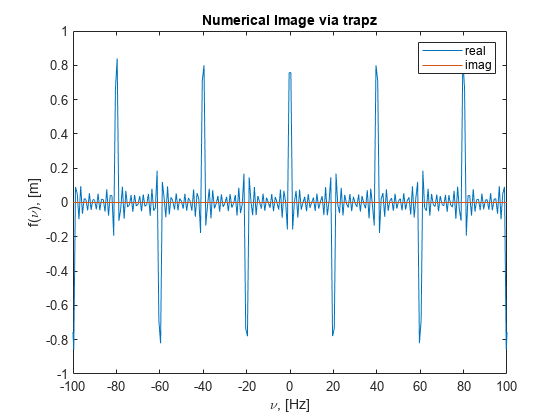

T = 50; % period of the rectangle function - f0
count = 2000;
t = linspace(-T, T, count);

rect_func = ones(size(t));
rect_func(t < -0.5 | t > 0.5) = 0;

% Define the frequency vector
f = linspace(-800, 800, 2000); % frequency vector

% Initialize the DFT vector
DFT = zeros(size(f));

% Compute the DFT for each frequency
for i = 1:length(f)
    DFT(i) = trapz(t, rect_func .* exp(-1j * 2 * pi * f(i) * t));
end

figure;
plot(f, real(DFT));
hold on;
plot(f, imag(DFT));
xlabel('\nu, [Hz]');
ylabel('f(\nu), [m]');
xlim([-100, 100])
title('Numerical Image via trapz');
legend('real', 'imag')


path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

Давайте возвращаться назад...

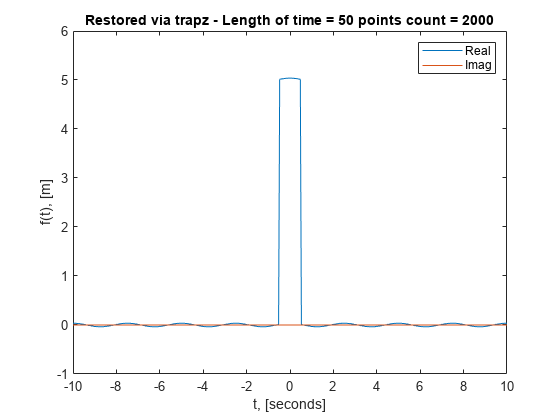

% Initialize the DFT vector
IDFT = zeros(size(f));

% Compute the DFT for each frequency
for i = 1:length(f)
    IDFT(i) = trapz(t, DFT .* exp(1j * 2 * pi * f(i) * t));
end

figure;
plot(t, real(IDFT));
hold on
plot(t, imag(IDFT));
title("Restored via trapz - Length of time = " + T + " points count = " + count)
xlabel('t, [seconds]');
xlim([-10, 10])
ylabel('f(t), [m]');
legend('Real','Imag')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

В последний раз повысим дискретизацию

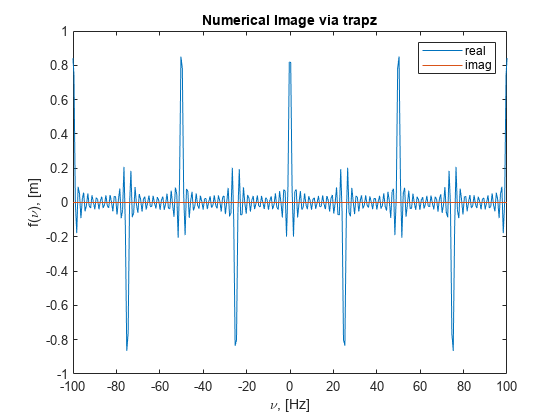

T = 50; % period of the rectangle function - f0
count = 2500;
t = linspace(-T, T, count);

rect_func = ones(size(t));
rect_func(t < -0.5 | t > 0.5) = 0;

% Define the frequency vector
f = linspace(-800, 800, 2500); % frequency vector

% Initialize the DFT vector
DFT = zeros(size(f));

% Compute the DFT for each frequency
for i = 1:length(f)
    DFT(i) = trapz(t, rect_func .* exp(-1j * 2 * pi * f(i) * t));
end

figure;
plot(f, real(DFT));
hold on;
plot(f, imag(DFT));
xlabel('\nu, [Hz]');
ylabel('f(\nu), [m]');
xlim([-100, 100])
title('Numerical Image via trapz');
legend('real', 'imag')


path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

Давайте возвращаться назад...

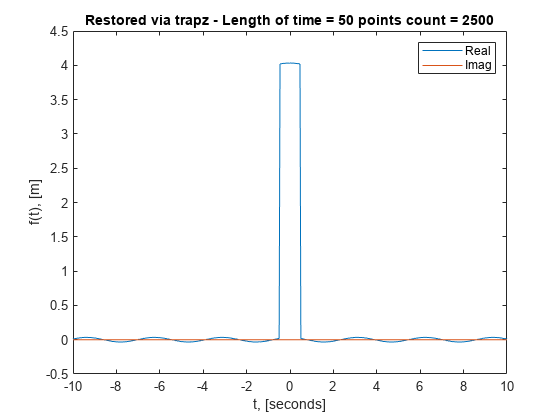

% Initialize the DFT vector
IDFT = zeros(size(f));

% Compute the DFT for each frequency
for i = 1:length(f)
    IDFT(i) = trapz(t, DFT .* exp(1j * 2 * pi * f(i) * t));
end

figure;
plot(t, real(IDFT));
hold on
plot(t, imag(IDFT));
xlim([-10, 10])
title("Restored via trapz - Length of time = " + T + " points count = " + count)
xlabel('t, [seconds]');
ylabel('f(t), [m]');
legend('Real','Imag')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

**В последний раз повысим дискретизацию - теперь точно**

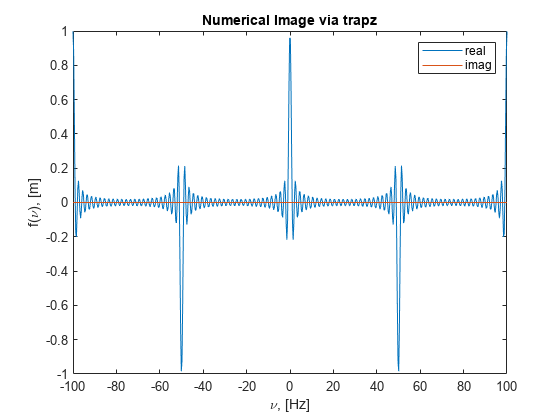

T = 50; % period of the rectangle function - f0
count = 5000;
t = linspace(-T, T, count);

rect_func = ones(size(t));
rect_func(t < -0.5 | t > 0.5) = 0;

% Define the frequency vector
f = linspace(-800, 800, 5000); % frequency vector

% Initialize the DFT vector
DFT = zeros(size(f));

% Compute the DFT for each frequency
for i = 1:length(f)
    DFT(i) = trapz(t, rect_func .* exp(-1j * 2 * pi * f(i) * t));
end

figure;
plot(f, real(DFT));
hold on;
plot(f, imag(DFT));
xlabel('\nu, [Hz]');
ylabel('f(\nu), [m]');
xlim([-100, 100])
title('Numerical Image via trapz');
legend('real', 'imag')


path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

Давайте возвращаться назад...

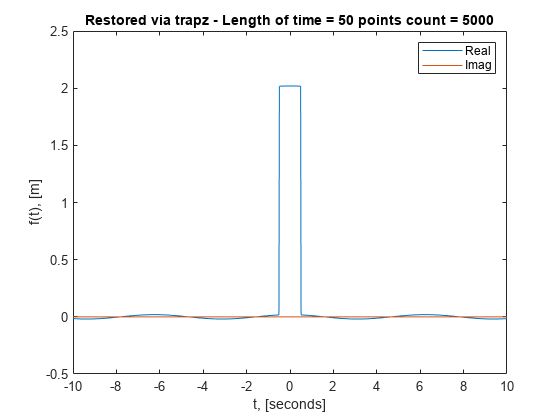

% Initialize the DFT vector
IDFT = zeros(size(f));

% Compute the DFT for each frequency
for i = 1:length(f)
    IDFT(i) = trapz(t, DFT .* exp(1j * 2 * pi * f(i) * t));
end

figure;
plot(t, real(IDFT));
hold on
plot(t, imag(IDFT));
title("Restored via trapz - Length of time = " + T + " points count = " + count)
xlabel('t, [seconds]');
xlim([-10, 10])
ylabel('f(t), [m]');
legend('Real','Imag')

path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab5\plotting';
fullpath = fullfile(path, "1_" + num2str(counter));
saveas(gcf, fullpath, 'png'); counter = counter + 1;

В итоге мы понимаем, что этот метод начинает хоть как-то приближаться к прямоугольной функции при 1000+ точек, но мы должны учитывать, что это приближение гармониками и верхушка прямоугольной функции никогда не станет идеально плоской, а также периодичность(плохо) останется при восстановлении. **Думаю, что это быстрый способ, но не точный**

## Все функции, используемые в скрипте

**Прямоугольная функция - задание 1**

function y = rectangle(t)
      V0 = 1/2;
      y = ones(size(t));
      y((t > V0)&(t >= 0)) = 0;
      y((t < -V0)&(t <= 0)) = 0;

end
% path = 'D:\programming\python\projects\AnalyzeDataWorkspace\Fourier_analysis\lab3\plotting';
% Name = task + "filter_a=" + a+"type ="+type;
% fullpath = fullfile(path, Name);
% saveas(gcf, fullpath, 'png');